## HPC Coursework

*Diego del Castillo*

clear
close all

tmax = 5;
% Define grid and apply initial conditions

dx = 1; %dx = dy
global Ny 
global Nx
Nx = 100;
Ny = 100;

[X,Y] = meshgrid(1:Nx,1:Ny);

myZeros = zeros(Ny,Nx);
u = zeros(Ny,Nx);
v = zeros(Ny,Nx);
h = zeros(Ny,Nx);
global g
g = 9.81;

%initial conditions functions
which_test_case = 4;

H = 10;
fun1 = @(x,y) H + exp(-(x-50)^2/25);
fun2 = @(x,y) H + exp(-(y-50)^2/25);
fun3 = @(x,y) H + exp(-((x-50)^2 + (y-50)^2)/25);
fun4 = @(x,y) H + exp(-((x-25)^2+(y-25)^2)/25) + exp(-((x-75)^2+(y-75)^2)/25);

switch which_test_case
    case 1
        initial_cond = fun1;
    case 2
        initial_cond = fun2;
    case 3
        initial_cond = fun3;
    case 4 
        initial_cond = fun4;
end

for x = 1:Nx
    for y = 1:Ny
        h(y,x) = initial_cond(x*dx,y*dx);
    end
end

global stencil
stencil = (1/dx) * [-1/60, 3/20, -3/4, 0, 3/4, -3/20, 1/60];

figure()
surf(X,Y,h)
title("start")
hold off

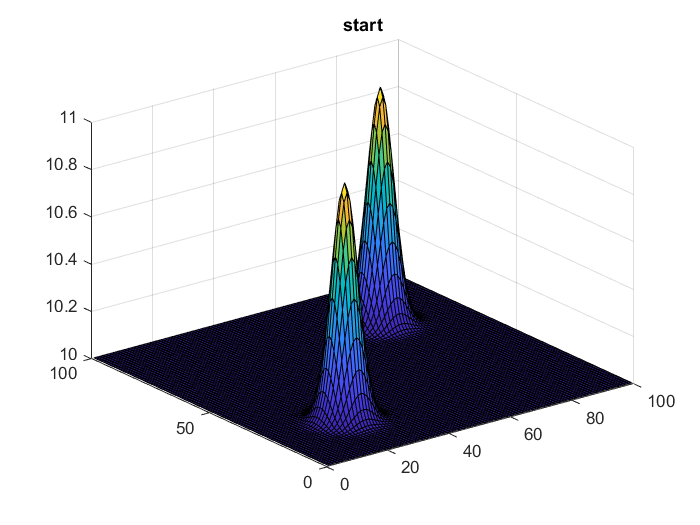

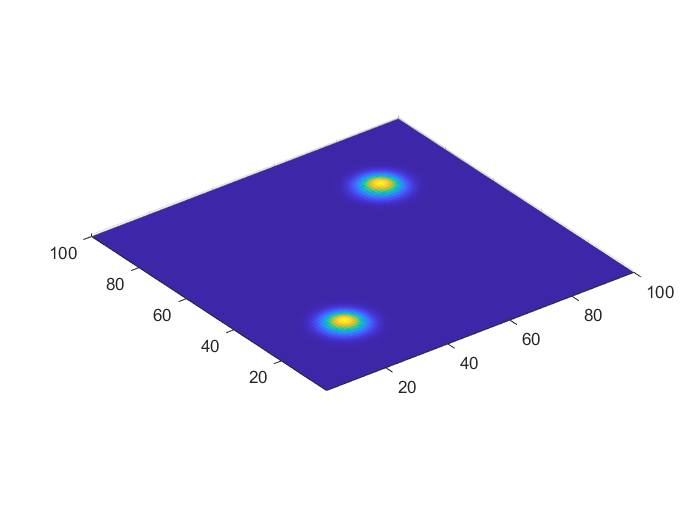

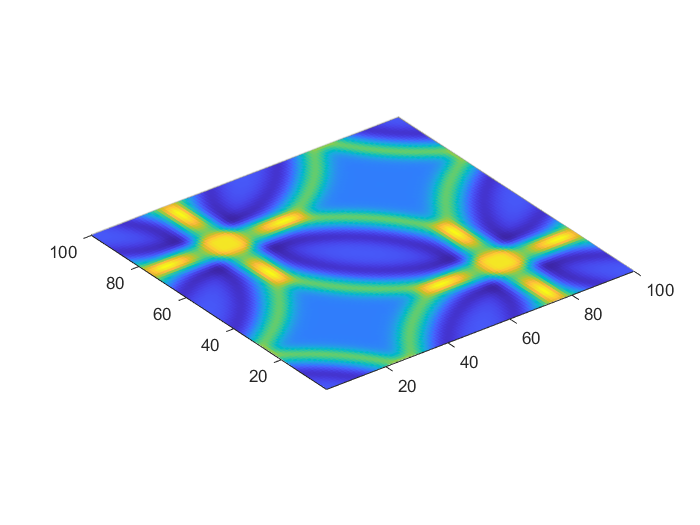

figure();title("Over time")
hold on

yn = [u;v;h];
dt = 0.1;

yn_start = [u;v;h];
counter = 0;
t = 0;
while t <= tmax
    
    
    
    k1 = calcF(yn);
    k2 = calcF(yn + dt*k1/2);
    k3 = calcF(yn + dt*k2/2);
    k4 = calcF(yn + dt*k3);

    yn = yn + (1/6) * (k1 + 2*k2 + 2*k3 + k4)*dt; %updating data next timestep
    
%     size(yn(2*Ny+1:3*Ny,:))
    clf    
    surf(X,Y,yn(2*Ny+1:3*Ny,:),'EdgeColor',"None")
    axis equal
    drawnow

%     pause(0.1)
    
    t = t+dt;
    counter = counter +1;
end

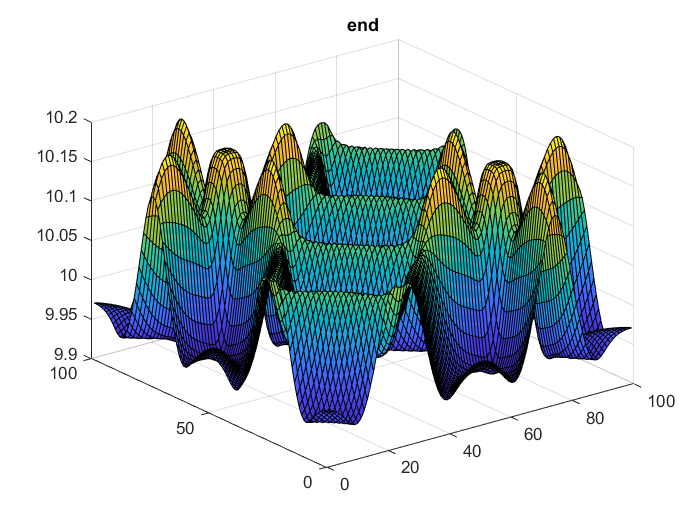

figure()
surf(X,Y,yn(2*Ny+1:3*Ny,:))
title("end")

% Functions

function f = calcF(yn) %find f
    global g;
    global Ny;
    
    u = yn(1:Ny,:);
    v = yn(Ny+1:2*Ny,:);
    h = yn(2*Ny+1:3*Ny,:);

    dhdx = derX(h);
    dhdy = derY(h);

    dudx = derX(u);
    dudy = derY(u);

    dvdx = derX(v);
    dvdy = derY(v);

    
    f1 = - (g*dhdx + u.*dudx) - (v.*dudy);
    f2 = - (u.*dvdx) - (g*dhdy + v.*dvdy);
    f3 = - (u.*dhdx + h.*dudx) - (v.*dhdy + h.*dvdy);

    f = [f1;f2;f3];
end

%derivative in y
function derivative_grid = derY(data)
    global Ny;
    global Nx;
    global stencil;

    derivative_grid = zeros(Ny,Nx);
    for col = 1:Nx
        for row = 1:Ny
           if 4<=row && row<=Ny-3
           derivative_grid(row,col) = sum(stencil.*...
                   [ data(row-3,col) , data(row-2,col), data(row-1,col),...
                     data(row,col) , data(row+1,col), data(row+2,col), ...
                     data(row+3,col)]);
           elseif row == 1
               derivative_grid(row,col) = sum(stencil.*...
                   [ data(Ny-2,col) , data(Ny-1,col), data(Ny,col),...
                     data(row,col) , data(row+1,col), data(row+2,col), ...
                     data(row+3,col)]);
           elseif row == 2
               derivative_grid(row,col) = sum(stencil.*...
                   [ data(Ny-1,col) , data(Ny,col), data(row-1,col),...
                     data(row,col) , data(row+1,col), data(row+2,col), ...
                     data(row+3,col)]);
           elseif row == 3
               derivative_grid(row,col) = sum(stencil.*...
                   [ data(Ny,col) , data(row-2,col), data(row-1,col),...
                     data(row,col) , data(row+1,col), data(row+2,col), ...
                     data(row+3,col)]);
           elseif row == Ny
               derivative_grid(row,col) = sum(stencil.*...
                   [ data(row-3,col) , data(row-2,col), data(row-1,col),...
                     data(row,col) , data(1,col), data(2,col), ...
                     data(3,col)]);
           elseif row == Ny-1
              derivative_grid(row,col) = sum(stencil.*...
                   [ data(row-3,col) , data(row-2,col), data(row-1,col),...
                     data(row,col) , data(row+1,col), data(1,col), ...
                     data(2,col)]);
           elseif row == Ny-2
            derivative_grid(row,col) = sum(stencil.*...
                   [ data(row-3,col) , data(row-2,col), data(row-1,col),...
                     data(row,col) , data(row+1,col), data(row+2,col), ...
                     data(1,col)]);
           else
               disp("Error calculating derivative wrt y")
           end
        end
    end
end

%derivative in x
function derivative_grid = derX(data)
    global Ny;
    global Nx;
    global stencil;

    derivative_grid = zeros(Ny,Nx);
    for col = 1:Nx
        for row = 1:Ny
           if 4<=col && col<=Nx-3
           derivative_grid(row,col) = sum(stencil.*...
                   [ data(row,col-3) , data(row,col-2), data(row,col-1),...
                     data(row,col) , data(row,col+1), data(row,col+2), ...
                     data(row,col+3)]);
           elseif col == 1
               derivative_grid(row,col) = sum(stencil.*...
                   [ data(row,Nx-2) , data(row,Nx-1), data(row,Nx),...
                     data(row,col) , data(row,col+1), data(row,col+2), ...
                     data(row,col+3)]);
           elseif col == 2
               derivative_grid(row,col) = sum(stencil.*...
                   [ data(row,Nx-1) , data(row,Nx), data(row,col-1),...
                     data(row,col) , data(row,col+1), data(row,col+2), ...
                     data(row,col+3)]);
           elseif col == 3
               derivative_grid(row,col) = sum(stencil.*...
                   [ data(row,Nx) , data(row,col-2), data(row,col-1),...
                     data(row,col) , data(row,col+1), data(row,col+2), ...
                     data(row,col+3)]);
           elseif col == Nx
               derivative_grid(row,col) = sum(stencil.*...
                   [ data(row,col-3) , data(row,col-2), data(row,col-1),...
                     data(row,col) , data(row,1), data(row,2), ...
                     data(row,3)]);
           elseif col == Nx-1
               derivative_grid(row,col) = sum(stencil.*...
                   [ data(row,col-3) , data(row,col-2), data(row,col-1),...
                     data(row,col) , data(row,col+1), data(row,1), ...
                     data(row,2)]);
           elseif col == Nx-2
            derivative_grid(row,col) = sum(stencil.*...
                   [ data(row,col-3) , data(row,col-2), data(row,col-1),...
                     data(row,col) , data(row,col+1), data(row,col+2), ...
                     data(row,1)]);
           else
               disp("Error calculating derivative wrt x")
           end
        end
    end
end